# **Arm Challenge: Image Sensor Data Treatment**

**Uso de Deep Learning e Computer Vision para identificar objetos no Gazebo**

**Parte 0: Testes**

- Sensor de Cor: Mostra uma foto

- Sensor de Profundidade: Mostra uma foto

- Teste de GTD

**Parte 1: Sensor de profundidade**

- Treino do YOLOX

- Treino de YOLOX mais tunado (Keller)

- Teste do YOLOX

- Tratamento de Canal

**Parte 2: Sensor de cor**

- Treino do YOLOX

- Teste do YOLOX

**Parte 3: Outros testes**

- Treino do Depth usando HUGE COCO

- Teste de Qualidade do Detector Treinado usando o Huge-Coco

**____________________________________________________________________________________**

#### >> PARTE 0: Testes

Sensor de Cor: Mostra uma foto

depthSub = rossubscriber('/camera/depth/image_raw',"sensor_msgs/Image","DataFormat","struct");

The global ROS node is not initialized. Use "rosinit" to start the global node and connect to a ROS network.

pause(1)

depthMsg = receive(depthSub,3);
depthImg = rosReadImage(depthMsg);

imshow(depthImg);

Sensor de Profundidade: Mostra uma foto

rgbSub   = rossubscriber('/camera/rgb/image_raw',"sensor_msgs/Image","DataFormat","struct");
pause(1)

rgbMsg   = receive(rgbSub,3);
rgbImg   = rosReadImage(rgbMsg);

imshow(rgbImg);

No caso em que há disparidade de canais, pode-se fazer `repmat(img,1,1,3) `para converter imagem cinza com um canal em imagem cinza com canais RGB.

Teste de GTD

data = load("C:\Users\Pedro\Downloads\gTruthDepthV1.mat");
gTDepthSensorV1 = data.gTruth;
gTDepthSensorV1

#### >> PARTE 1: Sensor de profundidade

Treino do YOLOX

%Extração dos dados do .mat
addpath('C:\Users\Pedro\Downloads\')
data = load("C:\Users\Pedro\Desktop\GTDConc\gTruthDepthV1.mat");
gTDepthSensorV1 = data.gTruth;

[imges,boxes] = objectDetectorTrainingData(gTDepthSensorV1);
gtdata = combine(imges,boxes);

%Shuffle e separação dos dados
gtSh = shuffle(gtdata);
numFiles = numpartitions(gtdata);

numTrain = floor(numFiles*0.7);
gtTrain = subset(gtSh,1:numTrain);

numVal = floor(numFiles*0.1);
gtVal = subset(gtSh,numTrain+1:numTrain+numVal);

gtTest = subset(gtSh,numTrain+numVal+1:numFiles);

%Inicialização e opcionamento do detector
classes = ["Bottle","Can"]

Detector = yoloxObjectDetector('small-coco',classes,InputSize=[640 640 3]);

options = trainingOptions(...
    "sgdm",...
    MaxEpochs=80,...
    MiniBatchSize=16,...
    Shuffle="every-epoch",...
    ValidationData=gtVal,...
    ValidationFrequency=2,...
    Plots="training-progress");

sgdmDetector = trainYOLOXObjectDetector(gtTrain,Detector,options);

Treino do YOLOX mais tunado (Keller)

%Extração dos dados do .mat

data = load("C:\Users\Pedro\Desktop\GTDConc\gTruthDepthV1.mat"); %Por o arquivo .mat aqui
gTDepthSensorV1 = data.gTruth;

[imges,boxes] = objectDetectorTrainingData(gTDepthSensorV1);
gtdata = combine(imges,boxes);

%Shuffle e separação dos dados
gtSh = shuffle(gtdata);
numFiles = numpartitions(gtdata);

numTrain = floor(numFiles*0.7);
gtTrain = subset(gtSh,1:numTrain);

numVal = floor(numFiles*0.1);
gtVal = subset(gtSh,numTrain+1:numTrain+numVal);

gtTest = subset(gtSh,numTrain+numVal+1:numFiles);

%Inicialização e opcionamento do detector
classes = ["Bottle","Can"]

Detector = yoloxObjectDetector('medium-coco',classes,InputSize=[640 640 3]);

%Bizu: 300 imagens

options = trainingOptions("sgdm", ...
    MaxEpochs=100, ...
    MiniBatchSize=16, ...
    InitialLearnRate=3e-4, ...
    Shuffle="every-epoch", ...
    ValidationData=gtVal, ValidationFrequency=200, ...
    OutputNetwork="best-validation-loss", ...
    Plots="training-progress");

shapeDetector = trainYOLOXObjectDetector(gtTrain,Detector,options);

Teste do YOLOX

imTest = imread("C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (4).jpeg");
[dbox,dscore,dlabel] = detect(shapeDetector,imTest);

labelsWithScores = string(dlabel) + ": " + string(dscore);
imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
imshow(imTested);

idx = dscore > 0.4;
dbox = dbox(idx, :);
dscore = dscore(idx);
dlabel = dlabel(idx);
labelsWithScores = string(dlabel) + ": " + string(round(dscore, 2));
imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
imshow(imTested);

Código para exportar o detector

save("C:\Users\Pedro\Downloads\Depth_Detector.mat","shapeDetector");

Tratamento de Canal de Cor

%Usando detetor pronto
load('C:\Users\Pedro\Downloads\Depth_Detector (1).mat',"shapeDetector");
imTest = imread("C:\Users\Pedro\Desktop\Dados\Captura de tela 2025-04-29 184845.png");
imTest = im2gray(imTest) %Compressão a um canal

imTest = 482×642 uint8 matrix
   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240
   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240
   240   240   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234   234
   240   234   189   189   189   189   189   189   189   189   189 

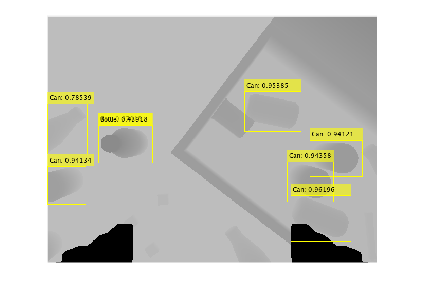

imTest = repmat(imTest,1,1,3); %Expansão do número de canais se houver só 1 canal 
[dbox,dscore,dlabel] = detect(shapeDetector,imTest);

labelsWithScores = string(dlabel) + ": " + string(dscore);
imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
imshow(imTested);

**Obs.** Pode ser necessário realizar uma normalização nas entradas das imagens, que podem ir do formato `unit8 `para `double` e haver saturação da imagem. Isso ocorre com o uso do `repmat`.

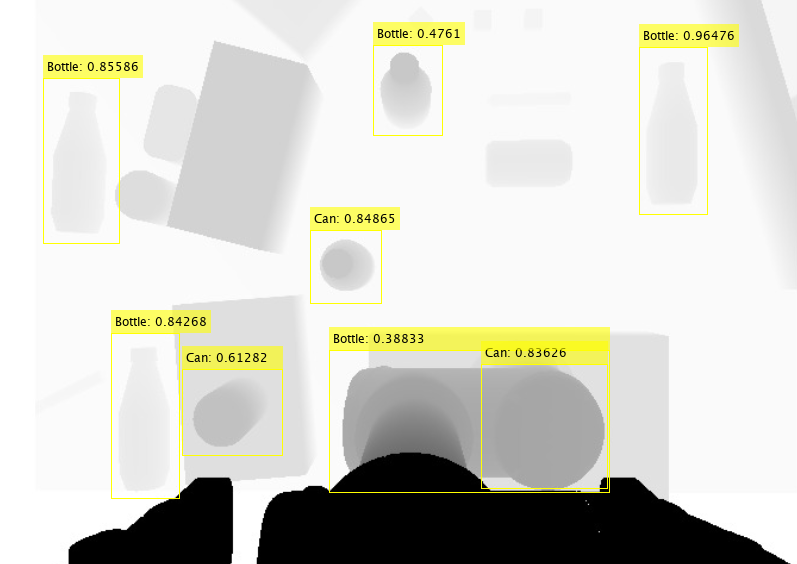

Desespero

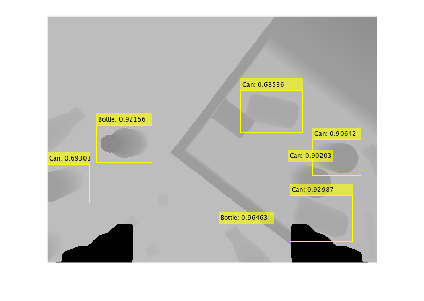

try
    shapeDetector = vision.loadYOLOXObjectDetector("C:\Users\Pedro\Downloads\Depth_Detector.mat");
catch ME
    error("Error in loading the detector");
end

% Leitura e pré-processamento da imagem
imTest = imread("C:\Users\Pedro\Desktop\Dados\Captura de tela 2025-04-29 184845.png");
imTest = im2gray(imTest); % Compressão a um canal
imTest = repmat(imTest, 1, 1, 3); % Expansão para 3 canais, se necessário

% Detecção e anotação
[dbox, dscore, dlabel] = detect(shapeDetector, imTest);
labelsWithScores = string(dlabel) + ": " + string(dscore);
imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);

% Exibição da imagem anotada
imshow(imTested);

#### >> PARTE 2: Sensor de cores

**Obs. (!!!) **A boa execução do sensor de cores pelo detetor exige a presença do `Automated Visual Inspection Library for Computer Vision Toolbox`.

Treino do colorido

%Extração dos dados do .mat

data = load(""); %Por o arquivo .mat aqui
gTColorS = data.gTruth;

[imges,boxes] = objectDetectorTrainingData(gTColorS);
gtdata = combine(imges,boxes);

%Shuffle e separação dos dados
gtSh = shuffle(gtdata);
numFiles = numpartitions(gtdata);

numTrain = floor(numFiles*0.7);
gtTrain = subset(gtSh,1:numTrain);

numVal = floor(numFiles*0.1);
gtVal = subset(gtSh,numTrain+1:numTrain+numVal);

gtTest = subset(gtSh,numTrain+numVal+1:numFiles);

%Inicialização e opcionamento do detector
classes = ["Yellow","Red","Blue","Green"]

Detector = yoloxObjectDetector('medium-coco',classes,InputSize=[640 640 3]);

options = trainingOptions("sgdm", ...
    MaxEpochs=130, ...
    MiniBatchSize=16, ...
    InitialLearnRate=3e-4, ...
    LearnRateSchedule="piecewise", LearnRateDropFactor=0.1, ...
    LearnRateDropPeriod=20, ...
    Momentum=0.9, L2Regularization=0.0005, ...
    Shuffle="every-epoch", ...
    ValidationData=gtVal, ValidationFrequency=200, ...
    FreezeSubNetwork="backbone", ...
    OutputNetwork="best-validation-loss", ...
    Plots="training-progress");

colorDetector = trainYOLOXObjectDetector(gtTrain,Detector,options);

Teste do YOLOX

imTest = imread("C:\Users\Pedro\Downloads\DepthTest.png");
[dbox,dscore,dlabel] = detect(colorDetector,imTest);

labelsWithScores = string(dlabel) + ": " + string(dscore);
imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
imshow(imTested);

idx = dscore > 0.4;
dbox = dbox(idx, :);
dscore = dscore(idx);
dlabel = dlabel(idx);
labelsWithScores = string(dlabel) + ": " + string(round(dscore, 2));
imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
imshow(imTested);

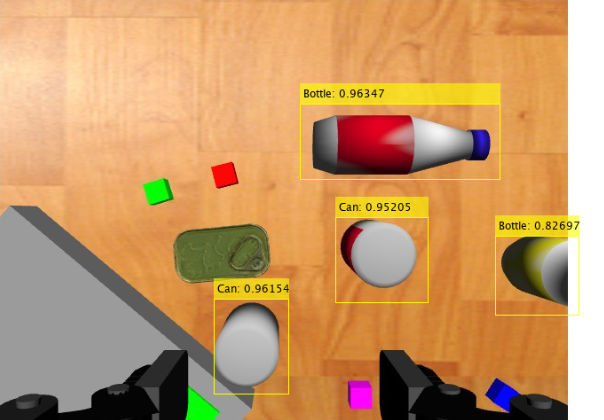

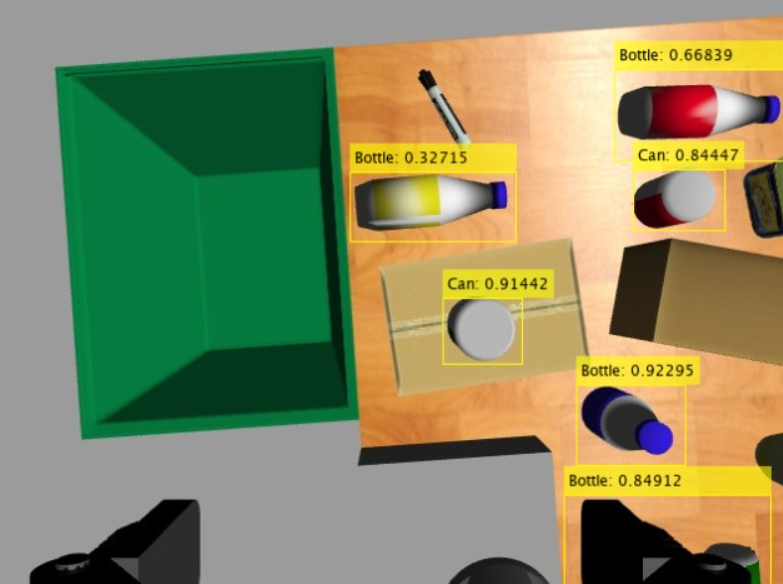

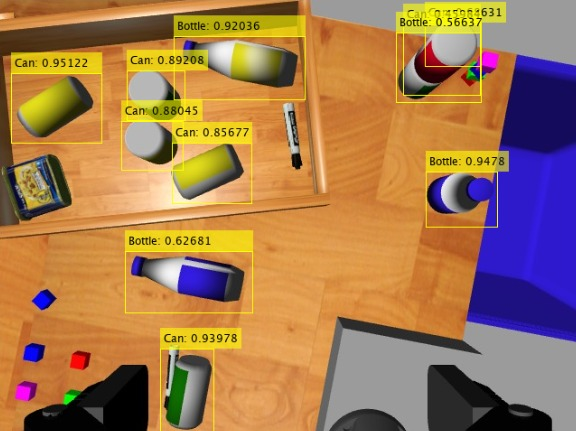

Desespero 2

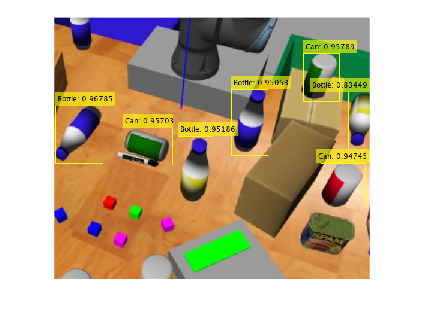

try
    colorDetector = vision.loadYOLOXObjectDetector(""); %Detector .mat archive
catch ME
    error("Error in loading the detector");
end

imTest = imread("C:\Users\Pedro\Downloads\Bunda.png");
[dbox,dscore,dlabel] = detect(colorDetector,imTest);

labelsWithScores = string(dlabel) + ": " + string(dscore);
imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
imshow(imTested);

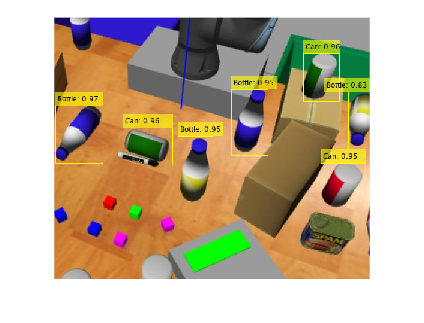


idx = dscore > 0.4;
dbox = dbox(idx, :);
dscore = dscore(idx);
dlabel = dlabel(idx);
labelsWithScores = string(dlabel) + ": " + string(round(dscore, 2));
imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
imshow(imTested);

#### >> PARTE 3: Outros testes

Treino do Depth usando HUGE COCO e opções mais tunadas

Pode ser usado em outro computador

Gera matriz de confusão e gráfico de confiança

data = load("C:\Users\Pedro\Desktop\Dados\gTruthDepthV1.mat") %MUDAR!

% Lista original de caminhos antigos (como cell array de strings)
caminhosAntigos = {
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185333.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185351.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185405.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185418.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185432.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185448.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185504.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185543.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185554.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185607.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185621.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185724.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185742.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185755.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185808.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185821.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185834.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185851.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185906.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185920.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185932.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185945.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190032.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190047.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190100.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190113.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190125.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190141.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190202.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190236.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190251.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190337.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190352.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190405.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190417.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190431.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190446.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190458.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190511.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190525.png'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (5).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (6).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (4).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (3).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (1).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (2).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (6).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52.jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (5).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (3).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (4).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (2).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (1).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51.jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.31.38.jpeg'
};

% Novo diretório
novoDiretorio = 'C:\Users\Pedro\Desktop\Dados'; %MUDAR!

% Inicializa o cell array de pares
alternativePaths = cell(size(caminhosAntigos));

% Gera o vetor com [caminho_antigo caminho_novo]
for i = 1:numel(caminhosAntigos)
    caminhoAntigo = caminhosAntigos{i};
    [~, nomeArquivo, ext] = fileparts(caminhoAntigo);
    caminhoNovo = fullfile(novoDiretorio, [nomeArquivo ext]);
    alternativePaths{i} = [string(caminhoAntigo), string(caminhoNovo)];
end

% Altere os caminhos do groundTruth
unresolvedPaths = changeFilePaths(data.gTruth, alternativePaths);

gTDepthSensorV1 = data.gTruth;

[imges,boxes] = objectDetectorTrainingData(gTDepthSensorV1);
gtdata = combine(imges,boxes);

%Shuffle e separação dos dados
gtSh = shuffle(gtdata);
numFiles = numpartitions(gtdata);

numTrain = floor(numFiles*0.7);
gtTrain = subset(gtSh,1:numTrain);

numVal = floor(numFiles*0.1);
gtVal = subset(gtSh,numTrain+1:numTrain+numVal);

gtTest = subset(gtSh,numTrain+numVal+1:numFiles);

%Inicialização e opcionamento do detector
classes = ["Bottle","Can"]

Detector = yoloxObjectDetector('large-coco',classes,InputSize=[640 640 3]);

%Bizu: 300 imagens

options = trainingOptions("sgdm", ...
    MaxEpochs=200, ...
    MiniBatchSize=8, ...
    InitialLearnRate=3e-4, ...
    LearnRateSchedule="piecewise", LearnRateDropFactor=0.1, ...
    LearnRateDropPeriod=20, ...
    Momentum=0.9, L2Regularization=0.0005, ...
    Shuffle="every-epoch", ...
    ValidationData=gtVal, ValidationFrequency=200, ...
    FreezeSubNetwork="backbone", ...
    OutputNetwork="best-validation-loss", ...
    Plots="training-progress");

shapeDetector = trainYOLOXObjectDetector(gtTrain,Detector,options);

save("C:\Users\Pedro\Downloads\Depth_Detector.mat","shapeDetector"); %MUDAR!

% Detecta objetos no conjunto de teste
results = detect(shapeDetector, gtTest);

% Avaliação da curva Precision-Recall
[ap, recall, precision] = evaluateDetectionPrecision(results, gtTest);

% Exibe a média da precisão (Average Precision)
fprintf('Average Precision (AP): %.2f\n', ap);

% Avaliação geral com matriz de confusão
[metrics, info] = evaluateObjectDetection(results, gtTest);

% Exibe as métricas principais
disp('Métricas por classe:');
disp(metrics);

% Mostra e plota a matriz de confusão
confMat = metrics.ConfusionMatrix;
disp('Matriz de Confusão:');
disp(confMat);

% Exibe gráfico da matriz de confusão
figure;
confusionchart(confMat, shapeDetector.Classes);
title('Matriz de Confusão de Detecção');
saveas(gcf, 'confusion_matrix.png'); % Salvar como imagem

Teste de Qualidade do Detector Treinado usando o Huge-Coco

load("C:\Users\Pedro\Downloads\Depth_Detector (1)","shapeDetector");
data = load("C:\Users\Pedro\Desktop\Dados\gTruthDepthV1.mat")

caminhosAntigos = {
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185333.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185351.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185405.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185418.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185432.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185448.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185504.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185543.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185554.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185607.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185621.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185724.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185742.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185755.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185808.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185821.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185834.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185851.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185906.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185920.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185932.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185945.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190032.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190047.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190100.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190113.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190125.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190141.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190202.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190236.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190251.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190337.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190352.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190405.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190417.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190431.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190446.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190458.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190511.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190525.png'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (5).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (6).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (4).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (3).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (1).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (2).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (6).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52.jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (5).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (3).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (4).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (2).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (1).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51.jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.31.38.jpeg'
};

% Novo diretório
novoDiretorio = 'C:\Users\Pedro\Desktop\Dados';

% Inicializa o cell array de pares
alternativePaths = cell(size(caminhosAntigos));

% Gera o vetor com [caminho_antigo caminho_novo]
for i = 1:numel(caminhosAntigos)
    caminhoAntigo = caminhosAntigos{i};
    [~, nomeArquivo, ext] = fileparts(caminhoAntigo);
    caminhoNovo = fullfile(novoDiretorio, [nomeArquivo ext]);
    alternativePaths{i} = [string(caminhoAntigo), string(caminhoNovo)];
end

% Altere os caminhos do groundTruth
unresolvedPaths = changeFilePaths(data.gTruth, alternativePaths);

gTDepthSensorV1 = data.gTruth;

[imges,boxes] = objectDetectorTrainingData(gTDepthSensorV1);
gtdata = combine(imges,boxes);

%Shuffle e separação dos dados
gtSh = shuffle(gtdata);
numFiles = numpartitions(gtdata);

numTrain = floor(numFiles*0.5);
gtTrain = subset(gtSh,1:numTrain);

numVal = floor(numFiles*0.1);
gtVal = subset(gtSh,numTrain+1:numTrain+numVal);

gtTest = subset(gtSh,numTrain+numVal+1:numFiles);

%Inicialização e opcionamento do detector
classes = ["Bottle","Can"]

results = detect(shapeDetector,gtTest, ...
    Threshold=0.4);
metrics = evaluateObjectDetection(results, ...
    gtTest);
[confMat,confLabels] = confusionMatrix(metrics);
confusionchart(confMat{1},confLabels)